clc
clear all


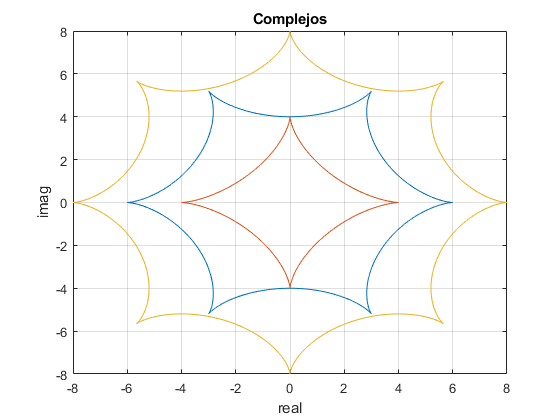

%Hipocicloides
fx = @(r1,r2,alpha) (r1-r2)*cos(alpha)+r2*cos(alpha*(1-(r1/r2)));
fy = @(r1,r2,alpha) (r1-r2)*sin(alpha)+r2*sin(alpha*(1-(r1/r2)));

a = 0:0.01:2*pi;

fxx6 = fx(6,1,a);
fyy6 = fy(6,1,a);
fxx4 = fx(4,1,a);
fyy4 = fy(4,1,a);
fxx3 = fx(8,1,a);
fyy3 = fy(8,1,a);

plot(fxx6,fyy6);
grid on
title('Complejos')
xlabel('real')
ylabel('imag')
hold on
plot(fxx4,fyy4)
hold on
plot(fxx3,fyy3)
hold off

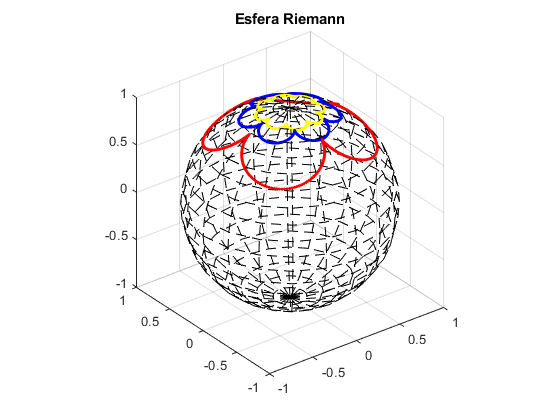


f_plot_coord_riemann(fxx6+1i*fyy6,"b");
hold on
f_plot_coord_riemann(fxx4+1i*fyy4,"r");
hold on
f_plot_coord_riemann(fxx3+1i*fyy3,'y');
title('Esfera Riemann');
hold off

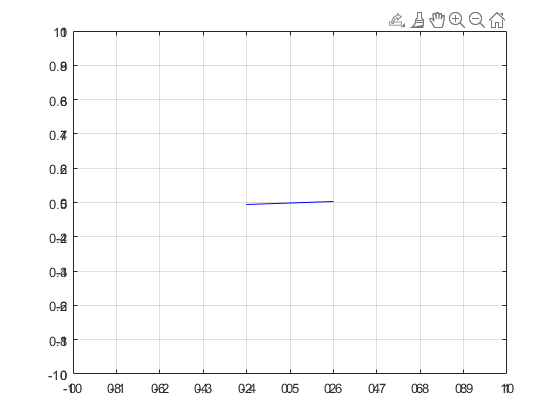

%%Using ginput
% 
% friemann = figure;
% fginput = figure;
% 
% hold off
% axes()
% axis([-10 10 -10 10])
% hold on
% grid on
% [x1,y1] = ginput(2);
% plot(x1,y1,'b');
% hold on
% vectx = [x1(1) x1(2)];
% vecty = [y1(1) y1(2)];
% 
% hold off
% 
% t = 0:0.001:1;
% param =@(t,x1,y1,x2,y2) [x1 y1] + t.*[x2-x1 y2-y1];
% 
% vectparamx = [];
% vectparamy = [];
% for tt=1:length(t) 
%    xx2 = param(t(tt),x1(1),y1(1),x1(2),y1(2));
%    vectparamx = horzcat(vectparamx, xx2(1));
%    vectparamy = horzcat(vectparamy, xx2(2)); 
% end
% box on

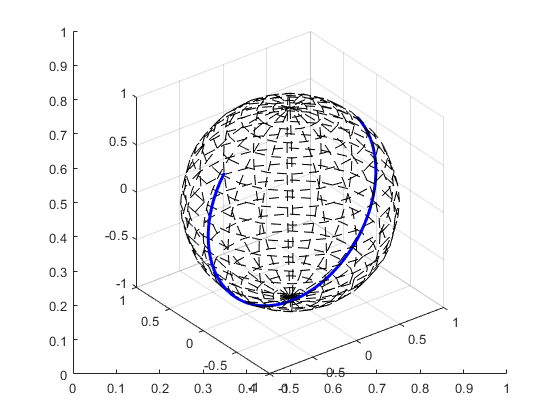

% f_plot_coord_riemann(vectparamx+1i*vectparamy,'b');
% 
% [x2, y2, button] = ginput(1);

% while isempty(x2) == false   %ESCAPAR CON UN ENTER
%     plot([vectx(end) x2],[vecty(end) y2],'b');
%     vectparamx = [];
%     vectparamy = [];
%     for tl = 1:length(t)
%         vectparam = param(t(tl),vectx(end), vecty(end),x2,y2);
%         vectparamx = horzcat(vectparamx, xx2(1));
%         vectparamy = horzcat(vectparamy, xx2(2));        
%     end
%     f_plot_coord_riemann(vectparamx+1i*vectparamy,'b')
%     
%     hold on 
%     vectx = horzcat(vectx, x2);
%     vecty = horzcat(vecty, y2);
% 
%     [x2, y2, button] = ginput(1);     
% end

% hold off
% 
% % disp(vectx);
% % disp(vecty);
% 
% % hold off
% % f_plot_coord_riemann(vectx+1i*vecty,'b')
% % hold off
% 
% 
% 
% 












